# Making Waves

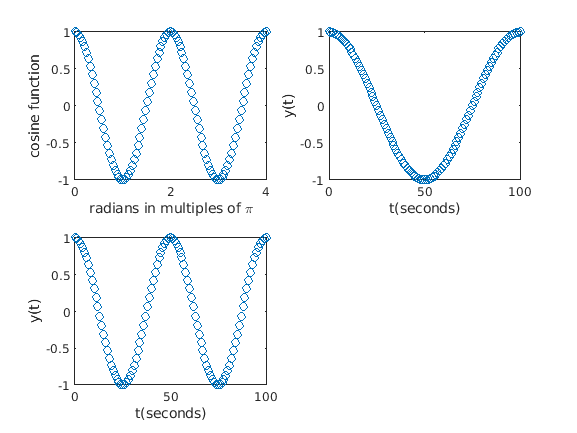

rads = 0:4*pi/100:4*pi;
subplot(2,2,1);
plot(rads/pi, cos(rads), 'o');
xlabel('radians in multiples of \pi');
ylabel('cosine function');
T = 100; %seconds
t = [0:T];
f = 1/T;
a = 2*pi*f;
y = cos(a*t);
subplot(2,2,2);
plot(t,y,'o');
xlabel('t(seconds)');
ylabel('y(t)');
% 2 waves
f = 2/T;
a = 2*pi*f;
y = cos(a*t);
subplot(2,2,3);
plot(t,y,'o');
xlabel('t(seconds)');
ylabel('y(t)');

## Phase Shifts

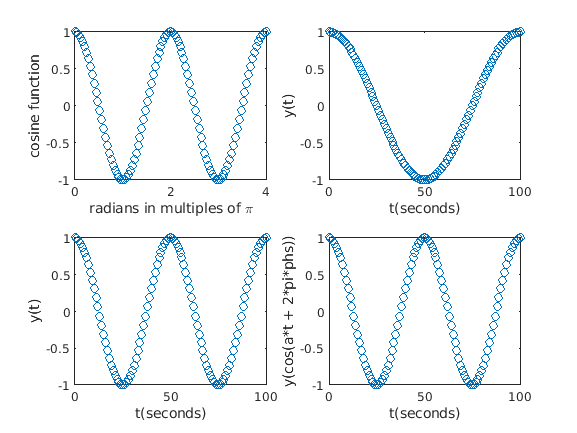

subplot(2,2,4);
for i=1:50
    phs=i/50;
    y=cos(a*t + 2*pi*phs);
    plot(t,y,'o');
    xlabel('t(seconds)');
    ylabel('y(cos(a*t + 2*pi*phs))');
    drawnow;
end

## Using Frequency

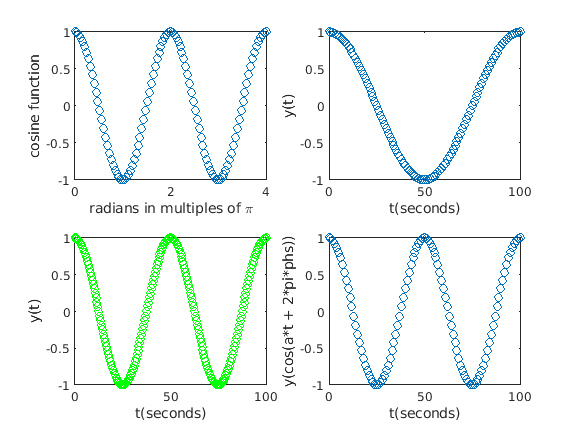

Fs = 2; %Hz
t = [0:1/Fs:T];
a = 2*pi*f;
y = cos(a*t);
subplot(2,2,3);
plot(t,y,'go');
xlabel('t(seconds)');
ylabel('y(t)');

## Making sound

T = 3;
Fs = 44100;
f = [330 247 208 165 123 82];
% Compute time vector, t
t = [0:1/Fs:T];
t(end) = [];
% Use a for-loop to construct y as a sum of cosines
y=0;
for i=1:length(f)
    a = 2*pi*f(i);
    y = y+cos(a*t);
end

## White Noise

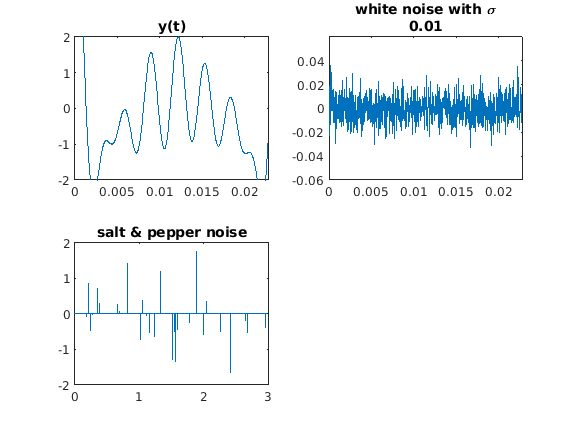

sigma = 0.01;
rng(0);
whoise = sigma*randn(size(y));
clf
subplot(2,2,1);
plot(t,y);
axis([0,5/220,-2,2]);
title("y(t)");
subplot(2,2,2);
plot(t,whoise);
axis([0,5/220,-.06,.06]);
title(["white noise with \sigma", sprintf("%.2f", sigma)]);
rng(0);
sprate=10;%Hz
spnoise = saltpeppernoise(sprate, t, Fs);
subplot(2,2,3);
plot(t,spnoise);
title("salt & pepper noise");